Textfile = load("W3.txt")

Textfile =            2         280        -312        8096          42          90         -10
           2         284        -248        8108          24          70         -31
           2         284        -248        8108          20          95         -36
           2         272        -252        8100          10          53         -22
           2         300        -208        8112          26         104         -41
           2         324        -216        8088          43          77          -9
           2         288        -248        8072          49          53         -34
           2         244        -264        8088          37          77         -29
           2         324        -268        8172          18          66         -33
           2         344        -240        8052          27          63         -24


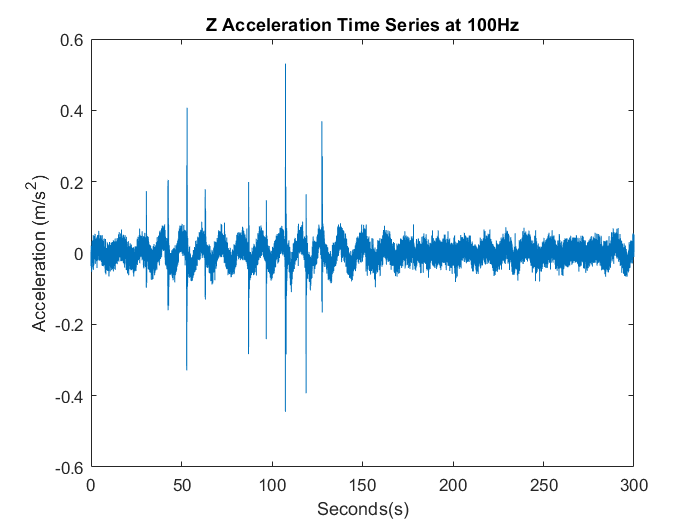

writematrix(Textfile, "W1.csv");
timeSeriesData = readtable("W1.csv");


N =  30000 - 1; 
timeSeriesData = detrend((timeSeriesData{:, 5}/8192*9.81)-9.81); %data is symmetric, *2 to account for contribution of other half 
fs = 100;
time = 1/fs*(0:(N));

plot(time(1:30000), timeSeriesData(1:30000)); %only plotting the real side of the dataset 
title("Z Acceleration Time Series at 100Hz");
xlabel("Seconds(s)");

ylabel("Acceleration (m/s^2)");